% Define the sequences
x_p = [1, 1, 1, 0.5, 0.5];
h_p = [1, 1, 0.75, 0.75, 0.25];

% Compute DFTs
X = fft(x_p);
H = fft(h_p);

% Multiply in frequency domain
Y = X .* H;

% Compute inverse DFT
y_p = ifft(Y);

% Plot the result
n = 1:length(y_p);
stem(n, real(y_p), 'filled');

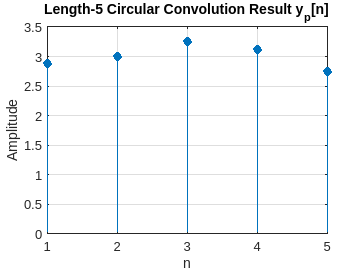

title('Length-5 Circular Convolution Result y_p[n]');
xlabel('n');
ylabel('Amplitude');
grid on;

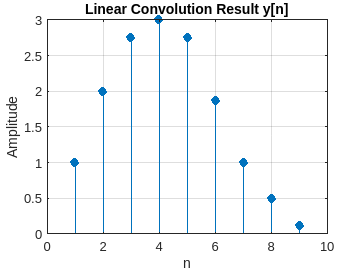

% Define the sequences and zero-pad to length 9
x = [1, 1, 1, 0.5, 0.5, zeros(1, 4)];
h = [1, 1, 0.75, 0.75, 0.25, zeros(1, 4)];

% Compute DFTs
X = fft(x);
H = fft(h);

% Multiply in frequency domain
Y = X .* H;

% Compute inverse DFT
y = ifft(Y);

% Plot the result
n = 1:length(y);
stem(n, real(y(1:9)), 'filled');
title('Linear Convolution Result y[n]');
xlabel('n');
ylabel('Amplitude');
grid on;